# MOOS ".klog" Processor

## Objective

For the sake of processing sonar data, hydrophone data, and insuring the Riptide 1MPUUV is operating correctly, we want to plot, for a given mission, where the AUV desires to be versus where the AUV actually is. The desired output of this script is file processable by the SonarTRX; This is likely a csv with GPS and depth data. 

## What this script does

This livescript is meant to easily process .klog files produced after the splitting process that occurs when using the MOOS alogviewer. The .klog files are kept in a single folder per mission with the name convention MOOSLog_DD_MM_YYYY_____HH_MM_SS_altvtmp. The primary files of interest are the GPS logs which contain date and time of the mission and the latitude and longitude information necessary to map the sonar data. We also would prefer to have altimeter data, but currently it doesn't seem to record on depth based missions, so NAV_DEPTH will have to do for now. Finally, for some comparison, we are interested in the log data for desired

## Variables wanted

GPS_YEAR, _DAY, _HOUR, _MINUTE, _SECOND, _LATITUDE, _LONGITUDE, _HEADING, _SPEED, _X, and _Y

DESIRED_DEPTH, _HEADING, and _SPEED

## NAV derivations (additional information)

Quick note: NAV increments roughly 10 times a second where GPS increments every 1 or 2 seconds. GPS data seems to line up fine and is never off by more than 0.00001 (or roughly a meter). So you could use NAV for latitude and longitude

X = GPS @ 2.0 sec, EKF @ 2.5 sec, LSQ @ 5.0 sec,

Y = GPS @ 2.0 sec, EKF @ 2.5 sec, LSQ @ 5.0 sec,

Z =  EKF @ 2.5 sec, LSQ @ 5.0 sec,

Depth = EKF @ 2.0 sec, LSQ @ 5.0 sec, DEPTH @ 1.0 sec,

Yaw  = EKF @ 2.0 sec, LSQ @ 5.0 sec, INS @ 1.0 sec,

Pitch = INS Speed = EKF

## Retrieve and convert variables into a useable matrix format

This code snippet asks the user to select the target folder before automatically selecting and processing the target .klog files.

target = {'DESIRED_DEPTH' 'DESIRED_HEADING' 'DESIRED_SPEED' 'GPS_YEAR' 'GPS_MONTH'...
    'GPS_DAY' 'GPS_HOUR' 'GPS_MINUTE' 'GPS_SECOND' 'NAV_LAT' 'NAV_LONG' 'NAV_DEPTH'};
Starget = [];
gotdir = uigetdir

gotdir = 'C:\Users\Matthew\Dropbox\WAVES\Wracksweeper\fieldTests\Mayfield_2020_11_09\MOOSLog_8_11_2020_____23_32_45_alvtmp'

for i = 1:length(target);
    filename = strcat(gotdir,'\',target{i},'.klog');
    formatSpec = '%25s%25s%25s%25s%[^\n\r]';
    fileID = fopen(filename,'r');
    dataArray = textscan(fileID, formatSpec, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string',  'ReturnOnError', false);
    fclose(fileID);
    raw = repmat({''},length(dataArray{1}),length(dataArray)-1);
    for col=1:length(dataArray)-1
        raw(1:length(dataArray{col}),col) = mat2cell(dataArray{col}, ones(length(dataArray{col}), 1));
    end
    numericData = NaN(size(dataArray{1},1),size(dataArray,2));
    for col=[1,2,3,4]
        % Converts text in the input cell array to numbers. Replaced non-numeric
        % text with NaN.
        rawData = dataArray{col};
        for row=1:size(rawData, 1)
            % Create a regular expression to detect and remove non-numeric prefixes and
            % suffixes.
            regexstr = '(?<prefix>.*?)(?<numbers>([-]*(\d+[\,]*)+[\.]{0,1}\d*[eEdD]{0,1}[-+]*\d*[i]{0,1})|([-]*(\d+[\,]*)*[\.]{1,1}\d+[eEdD]{0,1}[-+]*\d*[i]{0,1}))(?<suffix>.*)';
            try
                result = regexp(rawData(row), regexstr, 'names');
                numbers = result.numbers;
                
                % Detected commas in non-thousand locations.
                invalidThousandsSeparator = false;
                if numbers.contains(',')
                    thousandsRegExp = '^\d+?(\,\d{3})*\.{0,1}\d*$';
                    if isempty(regexp(numbers, thousandsRegExp, 'once'))
                        numbers = NaN;
                        invalidThousandsSeparator = true;
                    end
                end
                % Convert numeric text to numbers.
                if ~invalidThousandsSeparator
                    numbers = textscan(char(strrep(numbers, ',', '')), '%f');
                    numericData(row, col) = numbers{1};
                    raw{row, col} = numbers{1};
                end
            catch
                raw{row, col} = rawData{row};
            end
        end
    end
    I = ~all(cellfun(@(x) (isnumeric(x) || islogical(x)) && ~isnan(x),raw),1); % Find columns with non-numeric cells
    raw(:,I) = [];
    columnIndices = cumsum(~I);
    Starget.(target{i}) = cell2mat(raw);
    clearvars filename formatSpec fileID dataArray ans raw col numericData rawData row regexstr result numbers invalidThousandsSeparator thousandsRegExp I columnIndices;
end
clearvars i target

Combining GPS time doubles from Starget into a singular matrix

Note: Maybe later I will combine yr mon... sec into a single column. Ex YYMMDDHHMMSS

GPS_time = [Starget.GPS_YEAR(:,1) Starget.GPS_YEAR(:,2) Starget.GPS_MONTH(:,2)...
    Starget.GPS_DAY(:,2) Starget.GPS_HOUR(:,2) Starget.GPS_MINUTE(:,2)...
    Starget.GPS_SECOND(:,2)];

Filling gaps in GPS time

Note: Looks like GPS time skips a second (or more) every once in a while. It looks like the solution is to add a column that has integer values that match the start and end of the GPS_time reference column, but with no gaps and then use fillmissing to interpolate the missing seconds in GPS_time. Finally, the new reference column is removed.

GPS_time_rounded = [round(GPS_time(:,1)) GPS_time(:,2:end)];
%The following commented out code might be unneeded. 
%[~,uid_GPS_time_rounded] = unique(GPS_time_rounded(:,1),'stable');
%GPS_time_rounded_without_dup = GPS_time_rounded(uid_GPS_time_rounded,:)
%GPS_time_rounded_wo_dup_fill = fillmissing(GPS_time_rounded_without_dup,'linear')
%GPS_time = GPS_time_rounded_without_dup
GPS_time_ref = GPS_time_rounded(:,1)

GPS_time_ref =         4791
        4792
        4794
        4795
        4796
        4798
        4799
        4800
        4802
        4803


GPS_time_ref = [GPS_time_ref(1):GPS_time_ref(end)]'

GPS_time_ref =         4791
        4792
        4793
        4794
        4795
        4796
        4797
        4798
        4799
        4800


startYYYY = str2num(strcat(num2str(20),num2str(GPS_time_rounded(1,2))));
startMM = GPS_time_rounded(1,3);
startDD = GPS_time_rounded(1,4);
startHH = GPS_time_rounded(1,5);
startNN = GPS_time_rounded(1,6);
startSS = GPS_time_rounded(1,7);
endYYYY = str2num(strcat(num2str(20),num2str(GPS_time_rounded(end,2))));
endMM = GPS_time_rounded(end,3);
endDD = GPS_time_rounded(end,4);
endHH = GPS_time_rounded(end,5);
endNN = GPS_time_rounded(end,6);
endSS = GPS_time_rounded(end,7);
GPS_time_fill = datevec([datetime(startYYYY,startMM,startDD,startHH,startNN,startSS)...
    :seconds(1):datetime(endYYYY,endMM,endDD,endHH,endNN,endSS)]');
GPS_time = [GPS_time_ref GPS_time_fill]; %-GPS_time_ref(1)
GPS_time_header = {'ref' 'yr' 'mon' 'day' 'hr' 'min' 'sec'};
GPS_time_w_header = [GPS_time_header; num2cell([GPS_time])]

GPS_time_w_header = 985×7 cell array
    'ref'     'yr'      'mon'    'day'    'hr'    'min'    'sec'
    [4791]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 47]
    [4792]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 48]
    [4793]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 49]
    [4794]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 50]
    [4795]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 51]
    [4796]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 52]
    [4797]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 53]
    [4798]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 54]
    [4799]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 55]
    [4800]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 56]
    [4801]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 57]
    [4802]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 58]
    [4803]    [2020]    [ 11]    [  8]    [23]    [ 32]    [ 59]
    [4804]    [2020]    [ 11]    [  8]    [23]    [ 3

clearvars uid_GPS_time_rounded GPS_time_rounded GPS_time_rounded_without_dup...
    GPS_time_fill startYYYY startMM startDD startHH startNN startSS...
    endYYYY endMM endDD endHH endNN endSS GPS_time_header %GPS_time_ref

Combinging NAV Latitude and Longitude

Note: So GPS Lat/Long data disappears for over three minutes (presumably during dive), soooo, that means it will need to be derived from NAV LAT/LONG

NAV_latlong = [Starget.NAV_LAT(:,1) Starget.NAV_LAT(:,2) Starget.NAV_LONG(:,2)];

Reducing sample time to every second 

Note: In order to match up with GPS time, I am reducing the data set to grab lat/long data for each second instead of about 10 times per second.

NAV_latlong_rounded = [round(NAV_latlong(:,1)) NAV_latlong(:,2:end)];
[~,uid_NAV_latlong_rounded] = unique(NAV_latlong_rounded(:,1),'stable');
NAV_latlong_rounded_without_dup = NAV_latlong_rounded(uid_NAV_latlong_rounded,:);
NAV_latlong = NAV_latlong_rounded_without_dup;

Note: There are some gaps in the data. This example I am using only drops two seconds, but it could certainly be worse! Hopefully this interpolation solution works.

NAV_fill = interp1(NAV_latlong(:,1), NAV_latlong(:,2:3), GPS_time_ref);
NAV_latlong = [GPS_time_ref NAV_fill]; %-GPS_time_ref(1)
NAV_latlong_header = {'ref' 'lat' 'long'};
NAV_latlong_w_header = [NAV_latlong_header; num2cell(NAV_latlong)]

NAV_latlong_w_header = 985×3 cell array
    'ref'     'lat'        'long'     
    [4791]    [46.5099]    [-122.5687]
    [4792]    [46.5099]    [-122.5687]
    [4793]    [46.5099]    [-122.5687]
    [4794]    [46.5099]    [-122.5687]
    [4795]    [46.5099]    [-122.5687]
    [4796]    [46.5099]    [-122.5687]
    [4797]    [46.5100]    [-122.5687]
    [4798]    [46.5100]    [-122.5687]
    [4799]    [46.5100]    [-122.5687]
    [4800]    [46.5100]    [-122.5687]
    [4801]    [46.5100]    [-122.5687]
    [4802]    [46.5100]    [-122.5687]
    [4803]    [46.5101]    [-122.5687]
    [4804]    [46.5101]    [-122.5687]
    [4805]    [46.5101]    [-122.5687]
    [4806]    [46.5101]    [-122.5687]
    [4807]    [46.5102]    [-122.5687]
    [4808]    [46.5102]    [-122.5687]
    [4809]    [46.5102]    [-122.5687]
    [4810]    [46.5102]    [-122.5687]
    [4811]    [46.5102]    [-122.5687]
    [4812]    [46.5102]    [-122.5687]
    [4813]    [46.5102]    [-122.5687]
    [4814]    [46.5103] 

clearvars NAV_latlong_header uid_NAV_latlong_rounded NAV_latlong_rounded...
    NAV_latlong_rounded_without_dup NAV_fill

Plotting 

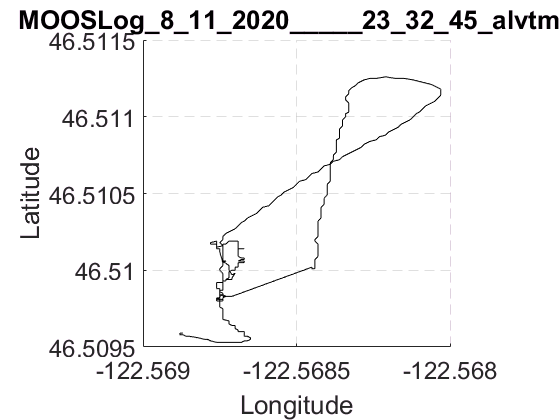

figure
plot(NAV_latlong(:,3),NAV_latlong(:,2),'k')
%xlim([5 32]), ylim([10 85])
xlabel('Longitude'), ylabel('Latitude')
%legend('Run 1')
title('MOOSLog_8_11_2020_____23_32_45_alvtmp')
grid on
set(gca,'GridLineStyle','--','FontSize',18)
pbaspect([1 1 1])
box off

legend boxoff    

Testing some fancy color stuff

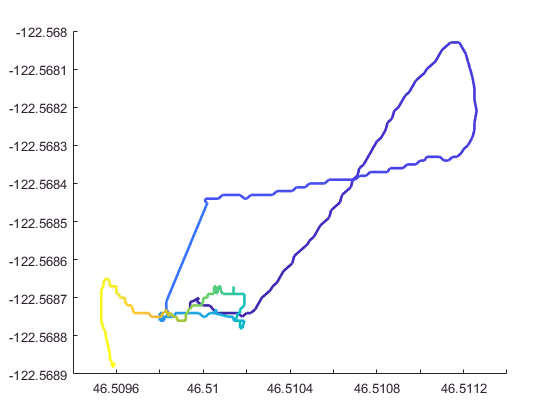

figure
x = NAV_latlong(:,2);
y = NAV_latlong(:,3);
z = zeros(size(x));
c = GPS_time_ref;
surface([x x],[y y],[z z],[c c],'facecol','no','edgecol','interp','linew',2)